# Models for Glass Identification Given Chemical Composition

## A Comparitive Study Between Random Forests and Decision Trees

**Ayliah Fani - 200044837**

## 1. Data Selection

% Data comes from: https://archive.ics.uci.edu/ml/datasets/glass+identification
glass_data_import = readtable("glass.csv");

## **2. Data Preparation**

### **A. Cleaning**

% remove id column & reindex
glass = glass_data_import(:,2:end);

% rename columns
glass.Properties.VariableNames = {'refractive_index' 'Na' 'Mg' 'Al' 'Si' 'K' 'Ca' 'Ba' 'Fe' 'type_of_glass'};

% check for missing values
missingvalues = sum(ismissing(glass))

missingvalues =      0     0     0     0     0     0     0     0     0     0



% split predictors and response
X = glass{:,1:end-1};
Y = glass{:,end};

% look at response class imbalance
tabulate(glass.type_of_glass)

  Value    Count   Percent
      1       70     32.71%
      2       76     35.51%
      3       17      7.94%
      4        0      0.00%
      5       13      6.07%
      6        9      4.21%
      7       29     13.55%


There is quite a bit of class imbalance that needs to be taken into consideration.

### **B. Descriptive Statistics**

allX = [glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass];
allY = [glass.refractive_index, glass.Na, glass.Mg, glass.Al, glass.Si, glass.K, glass.Ca, glass.Ba, glass.Fe];
titles = glass.Properties.VariableNames;

% statistical summary of each variable
format compact
summary(glass);

Variables:
    refractive_index: 214×1 double
        Values:
            Min        1.5111 
            Median     1.5177 
            Max        1.5339 
    Na: 214×1 double
        Values:
            Min        10.73  
            Median      13.3  
            Max        17.38  
    Mg: 214×1 double
        Values:
            Min            0  
            Median      3.48  
            Max         4.49  
    Al: 214×1 double
        Values:
            Min         0.29  
            Median      1.36  
            Max          3.5  
    Si: 214×1 double
        Values:
            Min        69.81  
            Median     72.79  
            Max        75.41  
    K: 214×1 double
        Values:
            Min            0  
            Median     0.555  
            Max         6.21  
    Ca: 214×1 double
        Values:
            Min         5.43  
         


stdev = std(X)

stdev =     0.0030    0.8166    1.4424    0.4993    0.7745    0.6522    1.4232    0.4972    0.0974


mn = mean(X)

mn =     1.5184   13.4079    2.6845    1.4449   72.6509    0.4971    8.9570    0.1750    0.0570


skew = skewness(X)

skew =     1.6140    0.4510   -1.1445    0.9009   -0.7253    6.5056    2.0327    3.3924    1.7420


### **C. Visualisation**

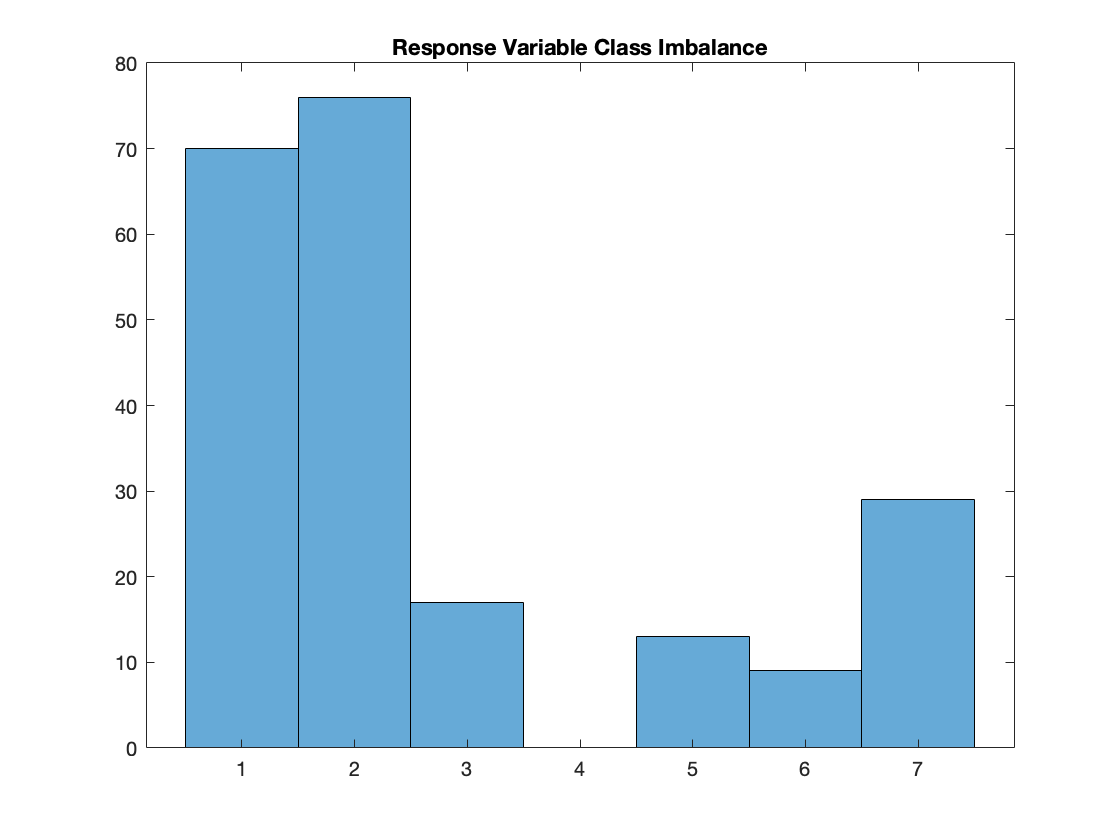

% % scatter plots of refractive index and glass oxide contents of each glass type
% for k=1:size(allX,2)
%     figure(k)
%     scatter(allX(:,k),allY(:,k))
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end
% 
% % box plots of refractive index and glass oxide content for each glass type
% for k=1:size(allX,2)
%     figure(k)
%     boxplot(allY(:,k),glass.type_of_glass)
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end

% histogram of class response occurance
histogram(Y)
title ('Response Variable Class Imbalance')

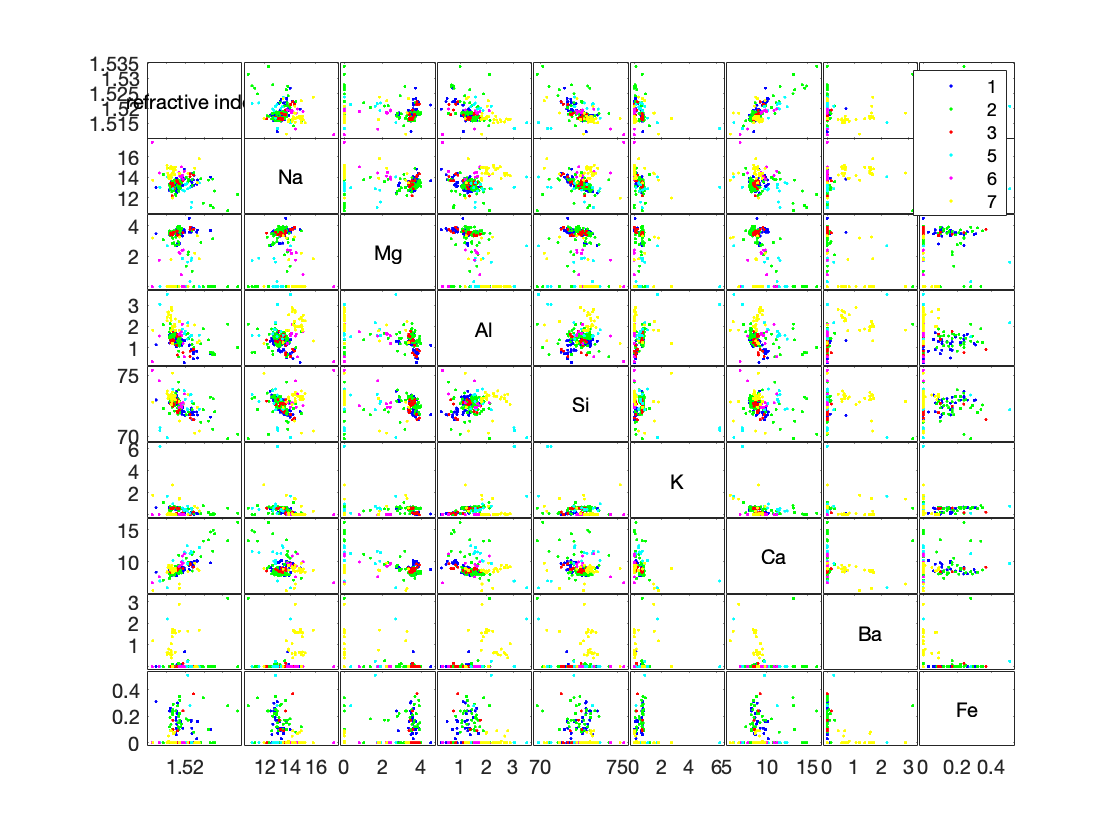


% scatterplot matrices
xnames = {'refractive index';'Na';'Mg';'Al';'Si';'K';'Ca';'Ba';'Fe'};
figure
[h,ax] = gplotmatrix(X,[],Y,[],[],[],[],'variable',xnames);

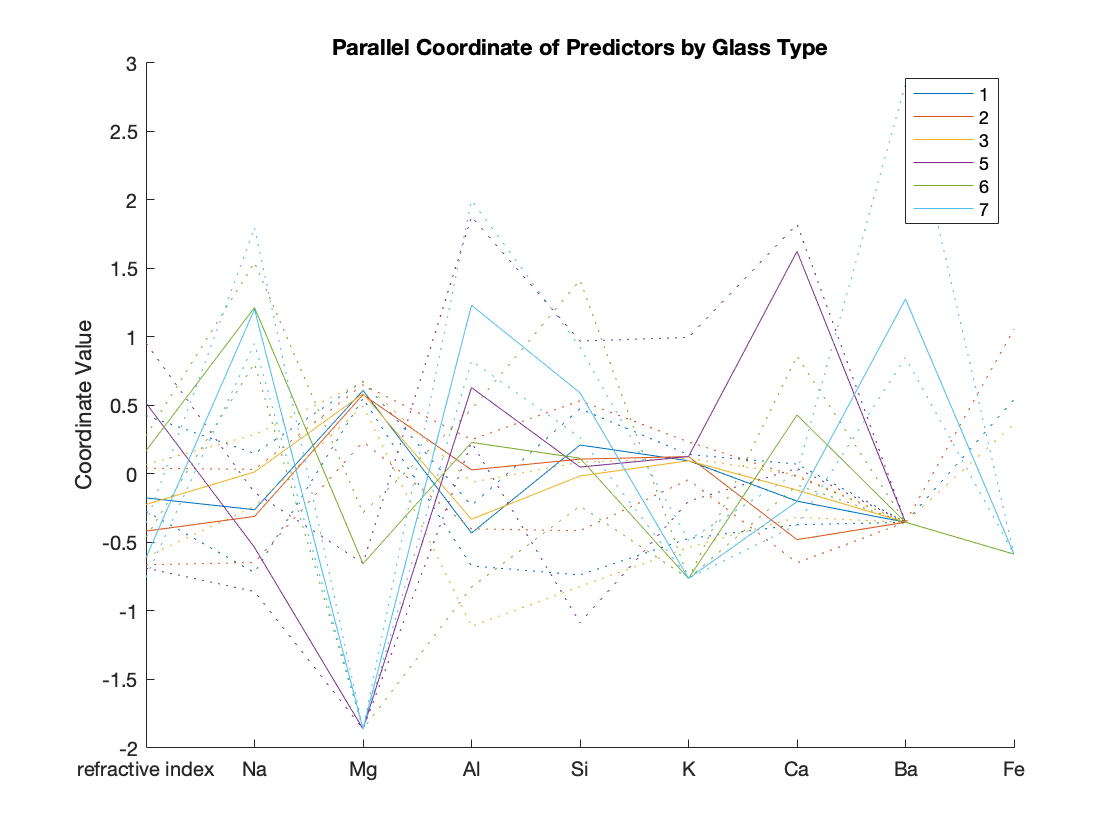


% parallel coordinate plot
parallelcoords(X,"Group",Y,'Labels',xnames, "Quantile",0.25, "Standardize","on")
title('Parallel Coordinate of Predictors by Glass Type')

from the box plots I might look into removing outliers since some ML techniques are sensitive to them. Glass type 4 has an incidence of zero, therefore it will not be considered during preditions.

[citation](https://www.mathworks.com/help/stats/visualizing-multivariate-data.html)

### **D. Partitioning the Data**

rng('default') % for reproducability
[m,n] = size(glass) ; 
idx = randperm(m) ;  % shuffle the rows 

%training data
train = glass{idx(1:round(m*0.70)),:}  ;
train_X = train(:,1:end-1);
train_Y = train(:,end);

%testing data
test = glass{idx(round(m*0.70)+1:round(m*0.85)),:} ;
test_X = test(:,1:end-1);
test_Y = test(:,end);

% validation data
val = glass{idx(round(m*0.85)+1:end),:} ;
val_X = val(:,1:end-1);
val_Y = val(:,end);

% 
% rng(1)                      % For reproducibility
% part = cvpartition(Y,'Holdout',0.2);
% 
% % training data
% istrain = training(part);   % Data for fitting
% train_X = X(istrain,:);
% train_Y = Y(istrain);
% 
% % testing data
% istest = test(part);        % Data for quality assessment
% test_X = X(istest,:);
% test_Y = Y(istest);
% 
% % look at count of classes present in the training set
% tabulate(train_Y)

`rng() `was changed multiple times to find the version which produced the best model and reproducability.

the percent holdout for `cvpartition` was also changed multiple times in order to find the percentage which yielded the best training model.

## **3. Model Selection**

# A. Random Forests

#### i. Model Training

Several classes are quite a low percentage of the data. This imbalance indicates that `RUSBoost` is an appropriate algorithm to use since the data is multiclass and skewed, but it is not within the scope of this course therefore `Bag` (Random Forests) will be used.

disp('#####################  RANDOM FOREST  ######################')

#####################  RANDOM FOREST  ######################


rng('default')            % For reproducibility
% N = sum(istrain);       % Number of observations in the training sample
N = size(train,1);
dt_op = templateTree('MaxNumSplits',N, 'Reproducible', true);
rf_mdl = fitcensemble(train_X,train_Y,'Method','Bag', ...
    'NumLearningCycles',200,'Learners',dt_op);

#### ii. Evaluate Performance

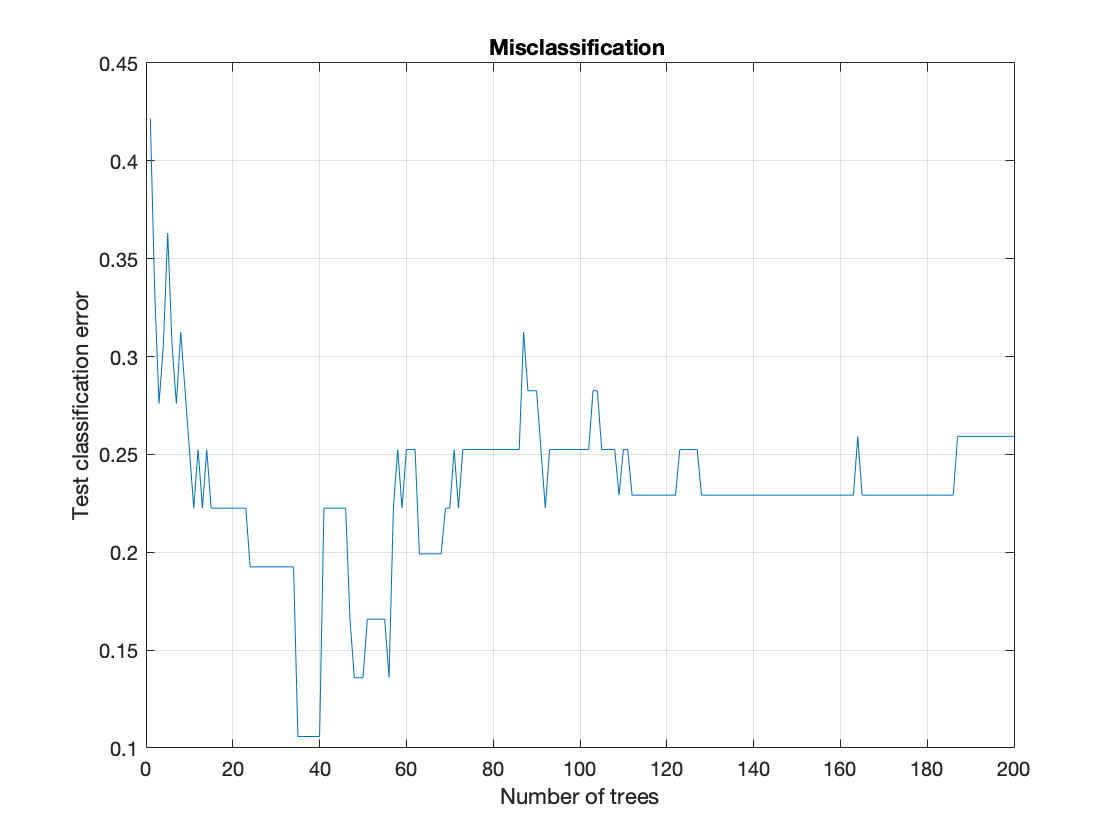

% Plot misclassification/loss against the number of trees in the ensemble.
figure;
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));
grid on;
xlabel('Number of trees');
ylabel('Test classification error');
title ('Misclassification ')

The ensemble reaches the minimum error between 130-134 trees with an error of ~26%

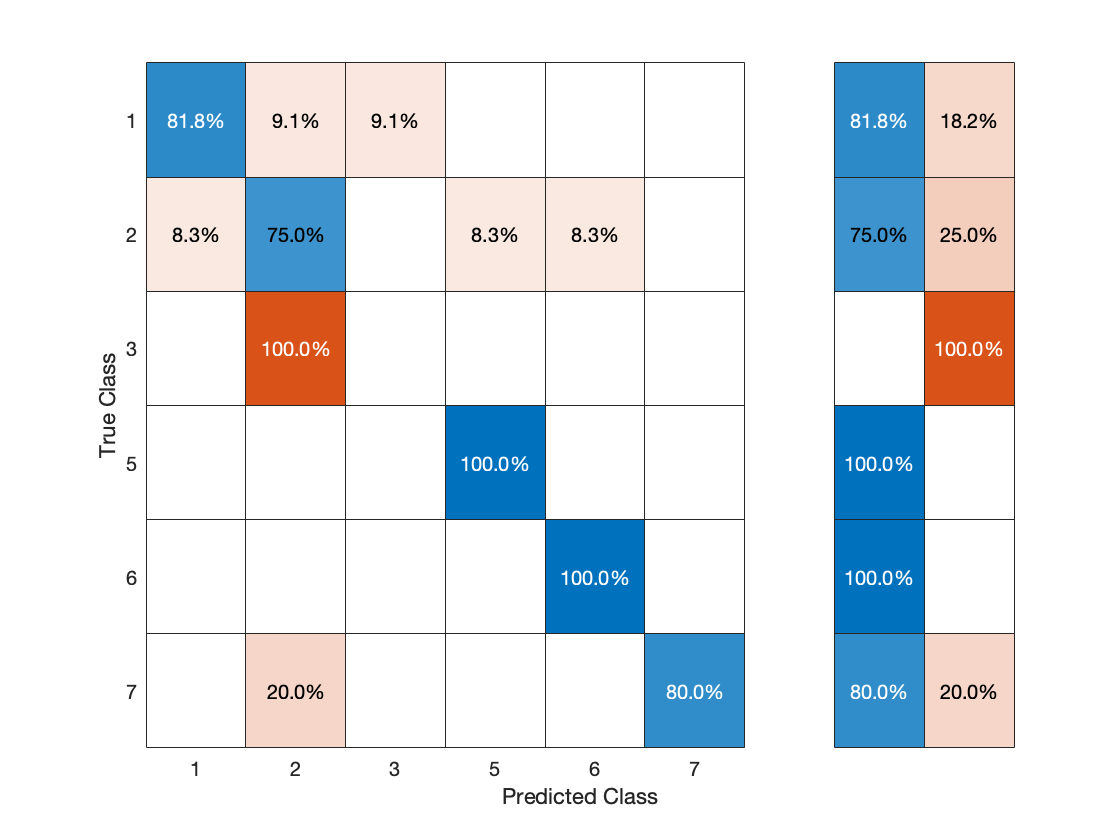

% confusion matrix
Yfit = predict(rf_mdl, test_X);
confusionchart(test_Y,Yfit,'Normalization','row-normalized','RowSummary','row-normalized')


% loss
rf_loss = loss(rf_mdl, test_X, test_Y)

rf_loss = 0.2592

**Cross Validation Error**

Generate a five-fold cross-validated ensemble.

% Perform cross-validation
rf_cv= crossval(rf_mdl, 'KFold', 5);

5-fold cross validation was used  since n-fold greater than 5 resulted in one of more of the unique class values is not present in one or more of the fold.

Examine the cross-validation loss as a function of the number of trees in the ensemble.

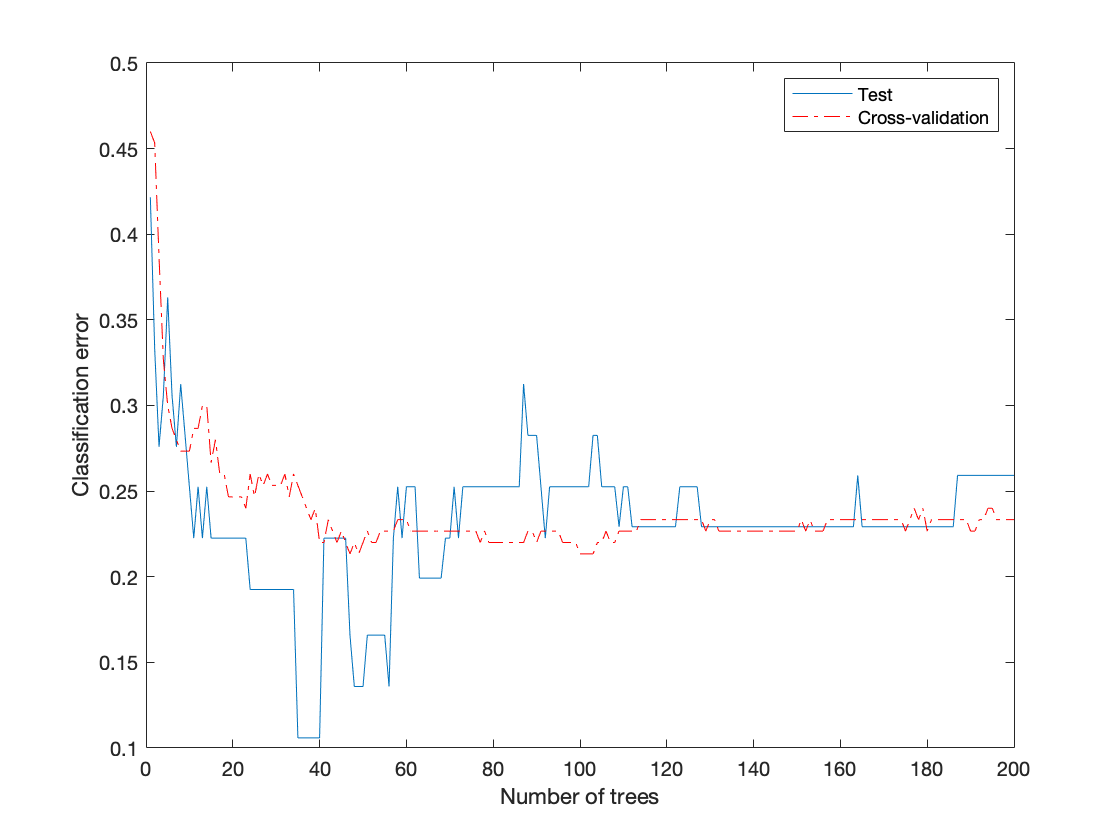

figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Location','NE')

Cross validating gives comparable estimates to those of the independent set.

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(rf_cv);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(rf_cv, 'LossFun', 'ClassifError');

**Out-of-Bag Error**

Generate the loss curve for out-of-bag estimates, and plot it along with the other curves.

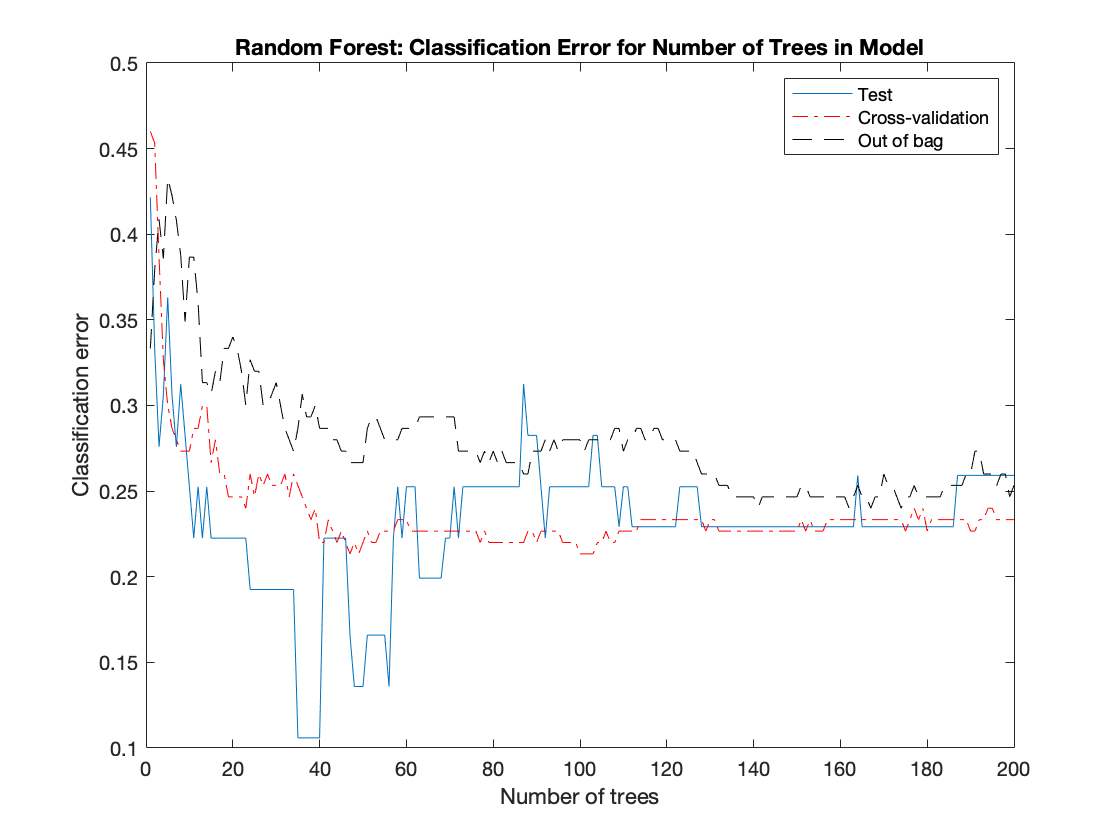

% out of bag estimates
figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
plot(oobLoss(rf_mdl,'mode','cumulative'),'k--')
hold off
xlabel('Number of trees')
ylabel('Classification error')
title('Random Forest: Classification Error for Number of Trees in Model')
legend('Test','Cross-validation','Out of bag','Location','NE')

#### iii. Optimisation

The classification error curve contains a minimum cross-validated misclassification rate occurring at the optimal number of trees in the ensemble.

% use the validation set to find where the minimum cross validated misclassification error
% [minErr, minErridx] = min(loss(rf_mdl,val_X,val_Y,'mode','cumulative'));
% 
% disp('BEST FROM VALIDATION SET')
% fprintf('\nMinimum classification error = %0.5f',minErr)
% fprintf('\nOptimal Num. Trees = %d',minErridx);

% find the minimum error and associated number of trees on the CV curve
disp('BEST FROM CV MODEL')

BEST FROM CV MODEL


rf_kfold = kfoldLoss(rf_cv,'mode','cumulative');
rf_minErr = min(rf_kfold);
rf_minErridx = min(find(rf_kfold==min(rf_kfold)));
fprintf('\nMinimum cross validated classification error = %0.5f',rf_minErr)


Minimum cross validated classification error = 0.21333

fprintf('\nOptimal Num. Trees = %d',rf_minErridx);


Optimal Num. Trees = 49

re-train the model with those values

#### iv. Final Preditions

Create a predictive random forest based on the optimal hyperparameters and the entire training set.

rng('default')
tFinal = templateTree('MaxNumSplits',N, 'Reproducible', true);

tic % calculate execution time for model
rf_Final = fitcensemble(train_X,train_Y,'Method', 'Bag', 'NumLearningCycles',rf_minErridx,...
    'Learners',tFinal);
toc

Elapsed time is 0.355327 seconds.


make predictions with the new model

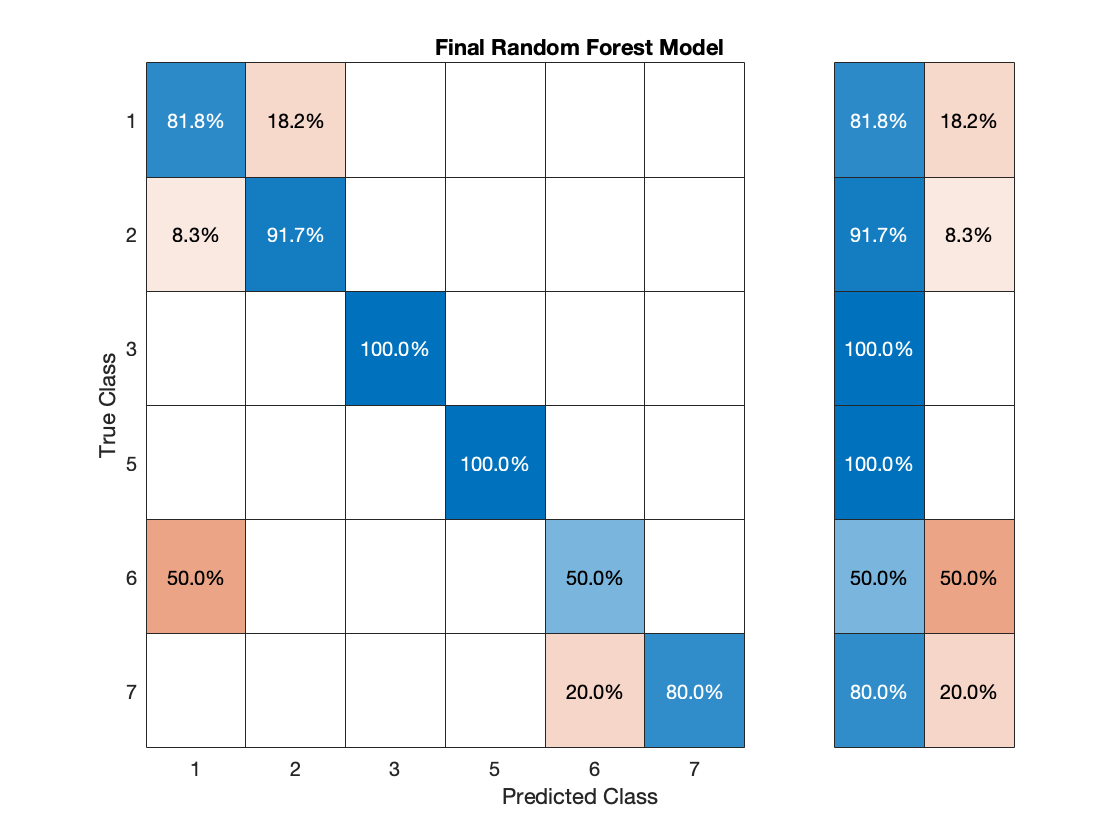

% confusion matrix
rf_finalfit = predict(rf_Final, test_X);
confusionchart(test_Y,rf_finalfit,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','Final Random Forest Model')


% loss
rf_loss_final = loss(rf_Final, test_X, test_Y)

rf_loss_final = 0.1359

# B. Decision Trees

#### **i. Model Training**

disp('##################  DECISION TREES  #############################')

##################  DECISION TREES  #############################


% grow a classification tree fromt the training set
rng('default')
dt_mdl = fitctree(train_X, train_Y, 'Reproducible',true);

% view the classification tree
view(dt_mdl,'Mode','graph');

#### ii. Evaluate Performance

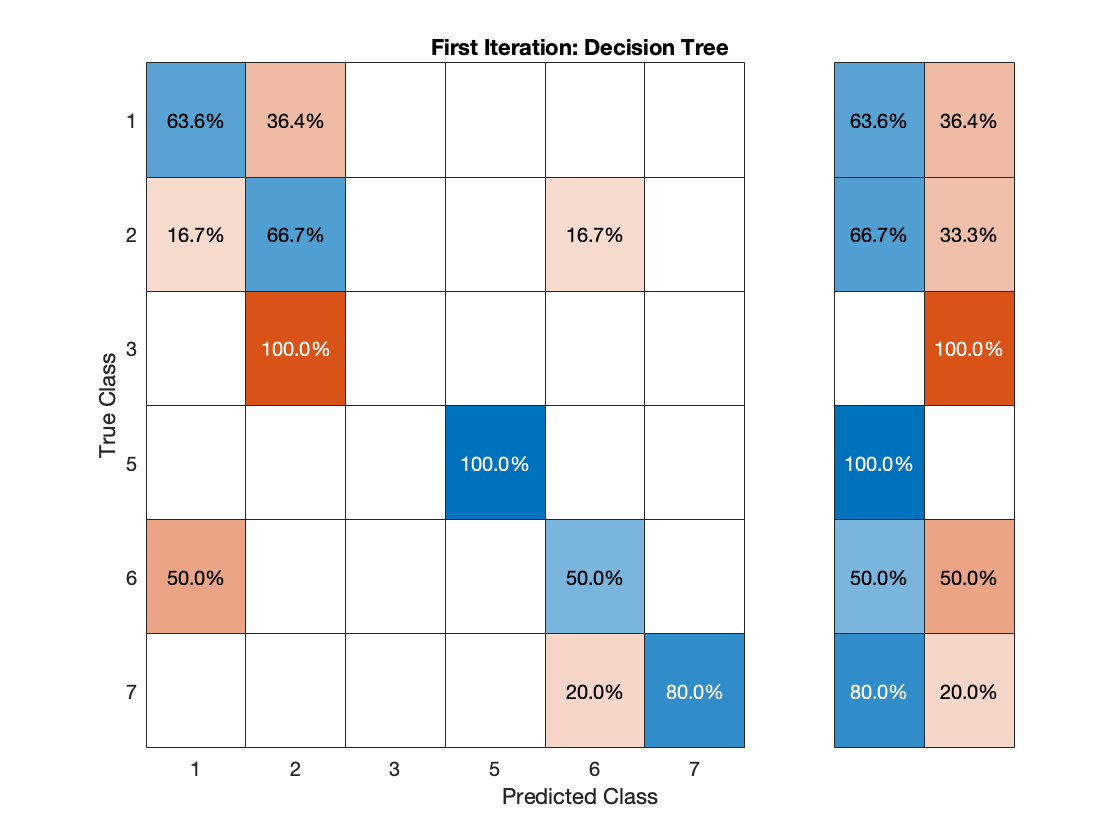

% confusion matrix
dt_fit = predict(dt_mdl, test_X);
confusionchart(test_Y,dt_fit,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','First Iteration: Decision Tree')


% calculate resubstitution/In-sample classification error
resuberror = resubLoss(dt_mdl)

resuberror = 0.1400


% loss
dt_loss = loss(dt_mdl, test_X, test_Y)

dt_loss = 0.3671

**Cross validation:**

% Perform cross-validation
dt_cv = crossval(dt_mdl, 'KFold', 5);
dt_cvloss = kfoldLoss(dt_cv)

dt_cvloss = 0.3600


% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(dt_cv);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(dt_cv, 'LossFun', 'ClassifError');

**Examine the classification error for each subtree/pruning level:**

Examine the training sample classification error for each subtree (or pruning level) excluding the highest level.

m = max(dt_mdl.PruneList) - 1;
trainLoss = resubLoss(dt_mdl,'SubTrees',0:m)

trainLoss =     0.1400
    0.1467
    0.1667
    0.1933
    0.2067
    0.2467
    0.2733
    0.3133
    0.4200
    0.5200


- The full, unpruned tree misclassifies about 14% of the training observations.

- The tree pruned to level 1 misclassifies about 15% of the training observations.

- The tree pruned to a stump misclassifies about 52% of the training observations.

Examine the validation sample classification error at each level excluding the highest level.

valLoss = loss(dt_mdl,val_X,val_Y,'SubTrees',0:m)

valLoss =     0.3391
    0.3391
    0.3391
    0.2716
    0.2716
    0.2036
    0.2036
    0.2114
    0.3191
    0.4755


- The full, unpruned tree misclassifies about 34% of the validation observations.

- The tree pruned to level 1 misclassifies about 34% of the validation observations.

- The tree pruned to a stump misclassifies about 48% of the validation observations.

From these observations we can look at pruning the tree to level 1 since there is not a significant increase in misclassification between the unpruned tree and the tree pruned to level 1. Even though the error increases, pruning is suitable since it simplifies the model and prevents overfitting.

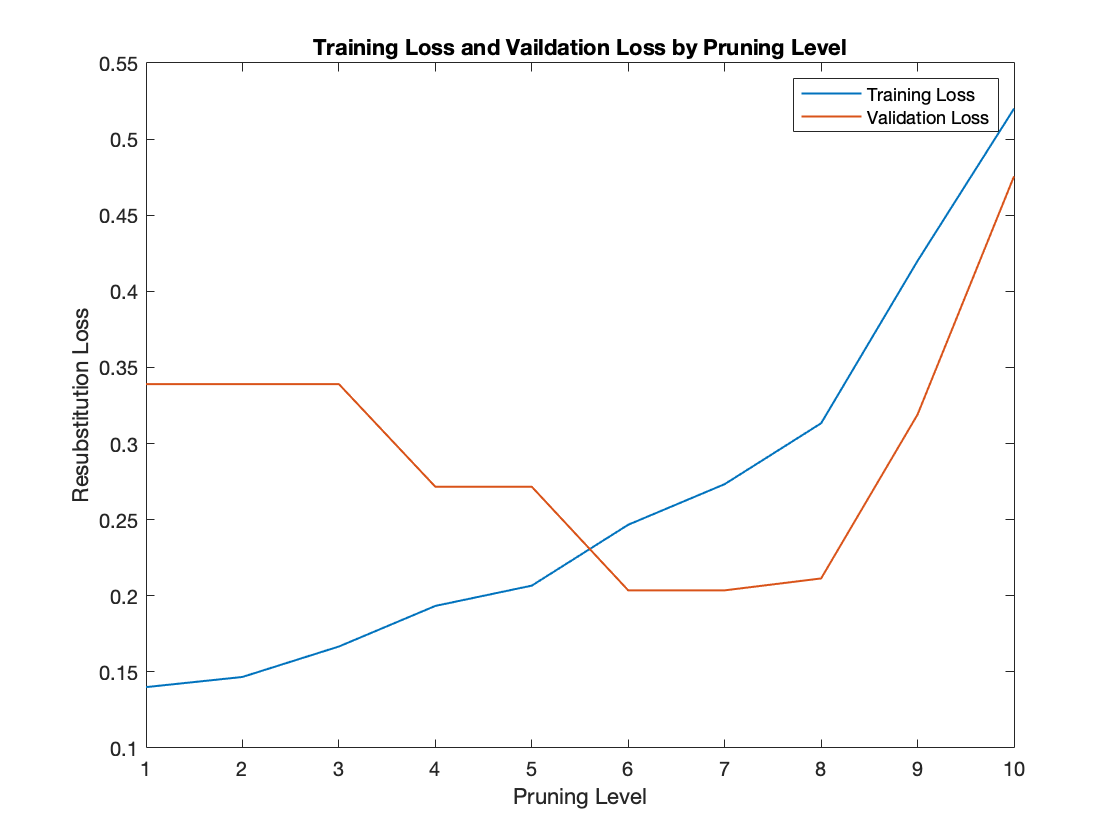

plot(trainLoss, 'LineWidth',1)
hold on
plot(valLoss, 'LineWidth',1)
hold off
title ('Training Loss and Vaildation Loss by Pruning Level')
xlabel('Pruning Level')
ylabel('Resubstitution Loss')
legend('Training Loss', 'Validation Loss')

To balance model complexity and out-of-sample performance, we can consider pruning `Mdl` to level 1 and see how the response is to the validation data.

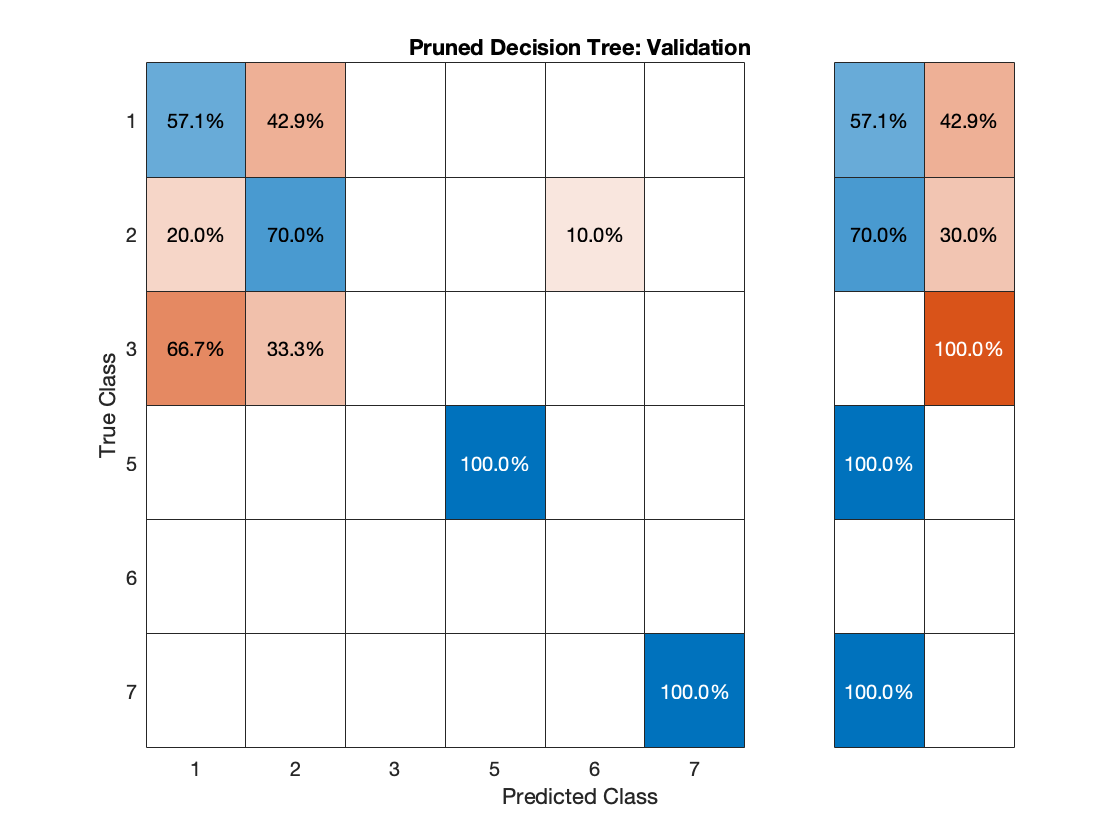

% Prune the model to level 1
dt_pruned = prune(dt_mdl,'Level',1);
% view(pruneMdl,'Mode','graph')

% confusion matrix
dt_prunePred= predict(dt_pruned, val_X);
confusionchart(val_Y,dt_prunePred,'Normalization','row-normalized','RowSummary','row-normalized', 'Title','Pruned Decision Tree: Validation')


% loss
dt_pruneLoss = loss(dt_pruned, val_X, val_Y)

dt_pruneLoss = 0.3391

[citation](https://www.mathworks.com/help/stats/classificationtree.resubloss.html#bunffiu-1)

**Predictor importance estimates:**

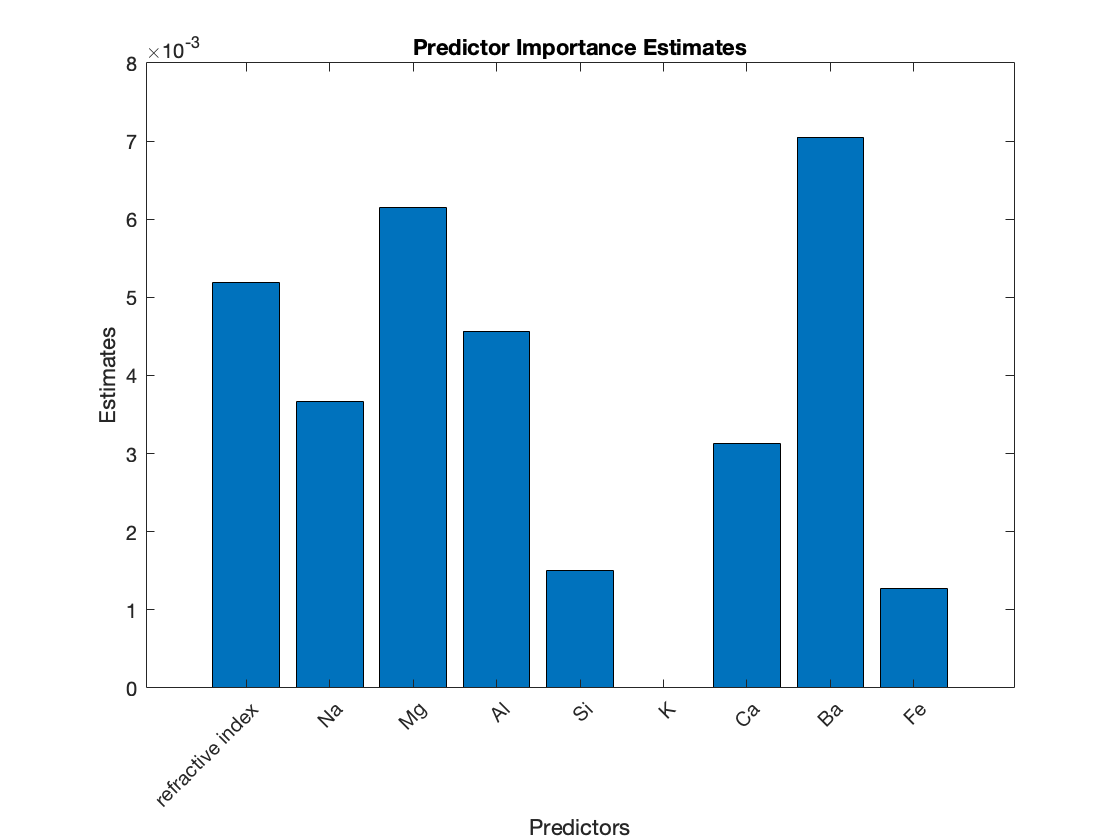

imp = predictorImportance(dt_mdl);

figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = {'refractive index' 'Na' 'Mg' 'Al' 'Si' 'K' 'Ca' 'Ba' 'Fe' };
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

[citation](https://www.mathworks.com/help/stats/fitctree.html#bvgg_9v)

#### **iii. Optimisation**

% dt_op = fitctree(test_X,test_Y,'OptimizeHyperparameters','auto');

**Select appropriate tree depth:**

Generate a spaced set of values from 1 through 30 via `leaves `that represents the minimum number of observations per leaf node.

Create cross-validated classification trees for the data and use to plot the cross-validated error versus minimum leaf size.

leaves = [1:30];
rng('default')
N = numel(leaves);
err = zeros(N,1);

for n=1:N
    dt_op = fitctree(train_X,train_Y,'CrossVal','On',...
        'MinLeafSize',leaves(n));
    err(n) = kfoldLoss(dt_op);
end

% plot cross-val error of each model against respective min. leaf size
plot(leaves,err);
xlabel('Min Leaf Size');
ylabel('cross-validated error');

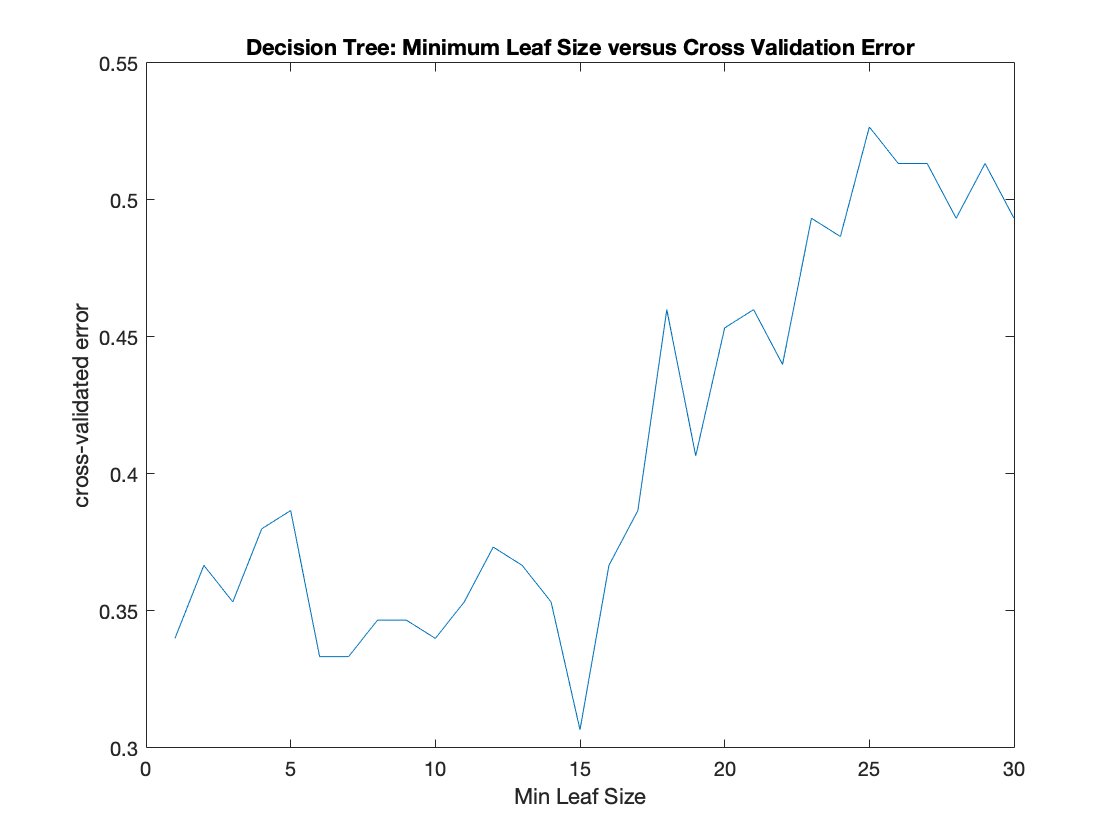

xlim([0.0 30.0])
ylim([0.300 0.550])
title('Decision Tree: Minimum Leaf Size versus Cross Validation Error')

% find the minimum on the graph
dt_minErr = min(err);
dt_minErridx = find(err==min(err));


fprintf('\nMinimum classification error = %0.5f',dt_minErr)
fprintf('\nOptimal Num. Leaves = %d',dt_minErridx);

From the graph the best leaf size is approximately 15..

Compare the optimal tree with at least `dt_minErridx` = ____ observations per leaf with the default tree, which uses `10` observations per parent node and `1` observation per leaf.

view(dt_mdl,'Mode','Graph');

OptimalTree = fitctree(train_X,train_Y,'MinLeafSize',dt_minErridx);
view(OptimalTree,'mode','graph');


Minimum classification error = 0.30667

resubOpt = resubLoss(OptimalTree);


Optimal Num. Leaves = 15

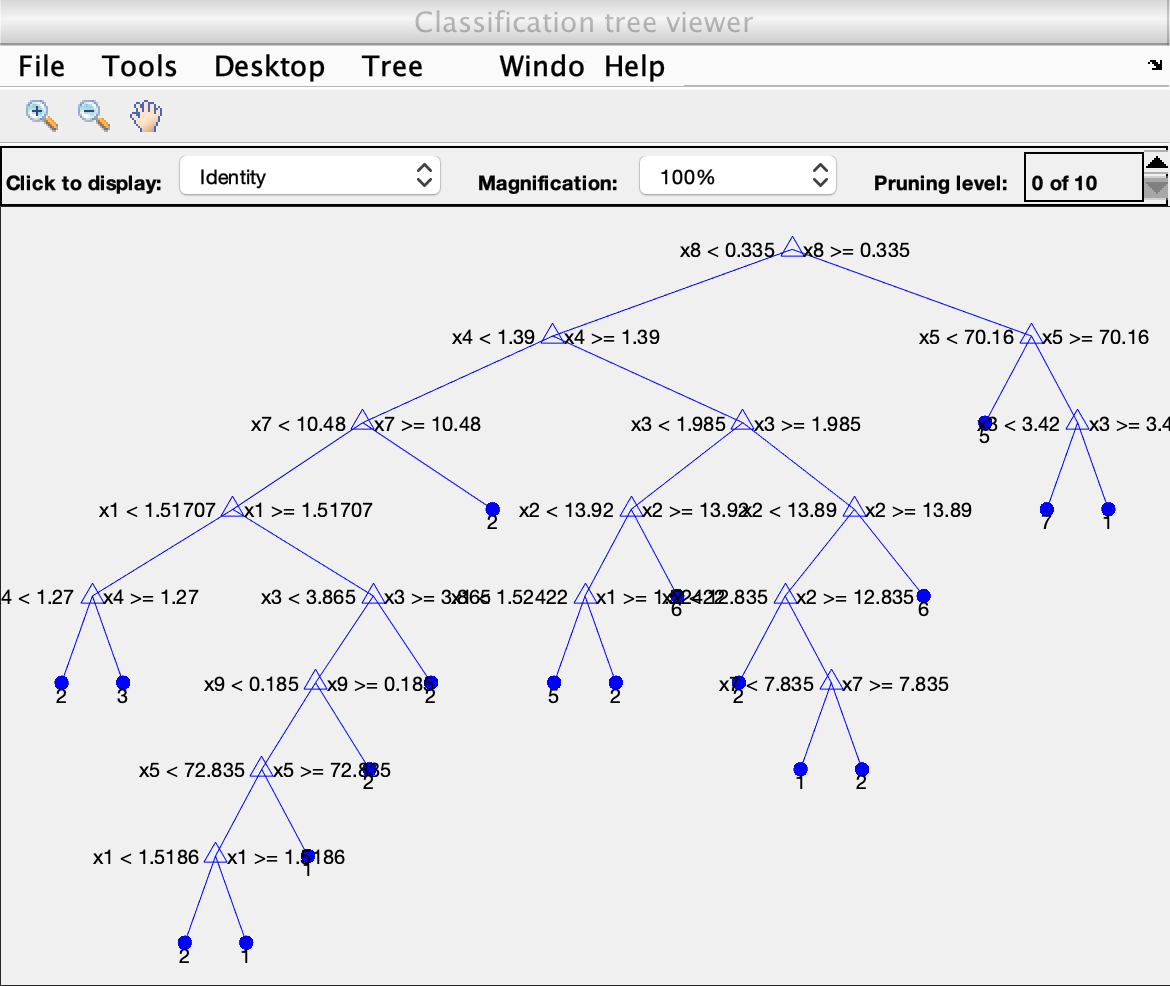

lossOpt = kfoldLoss(crossval(OptimalTree));

resubDefault = resubLoss(dt_mdl);
lossDefault = kfoldLoss(crossval(dt_mdl));


resubOpt,resubDefault,lossOpt,lossDefault

The optimal tree is smaller,  gives a higher error resub error and lower loss error when compared to the initial tree. The min leaf size found during optimisation is consistent with that found when observing classification error in each subtree and model evaluation. Therefore the final model will use this value. 

[citation](https://www.mathworks.com/help/stats/improving-classification-trees-and-regression-trees.html#bsx6u4u)

#### iv. Final Model, Predictions, & Evaluation

% create the final model
rng(1) %for reproducability
tic
dt_final = fitctree(train_X,train_Y,'MinLeafSize',dt_minErridx);

toc

% view the classification tree

view(dt_final,'Mode','graph');


resubOpt = 0.2600

resubDefault = 0.1400

lossOpt = 0.3867

lossDefault = 0.3600

% make predicitions
dt_finalPred = predict(dt_final, test_X);

%confusion matrix
confusionchart(test_Y,dt_finalPred,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','Final Decision Tree')

% calculate resubstitution/In-sample classification error
resuberror = resubLoss(dt_final)

Elapsed time is 0.018260 seconds.


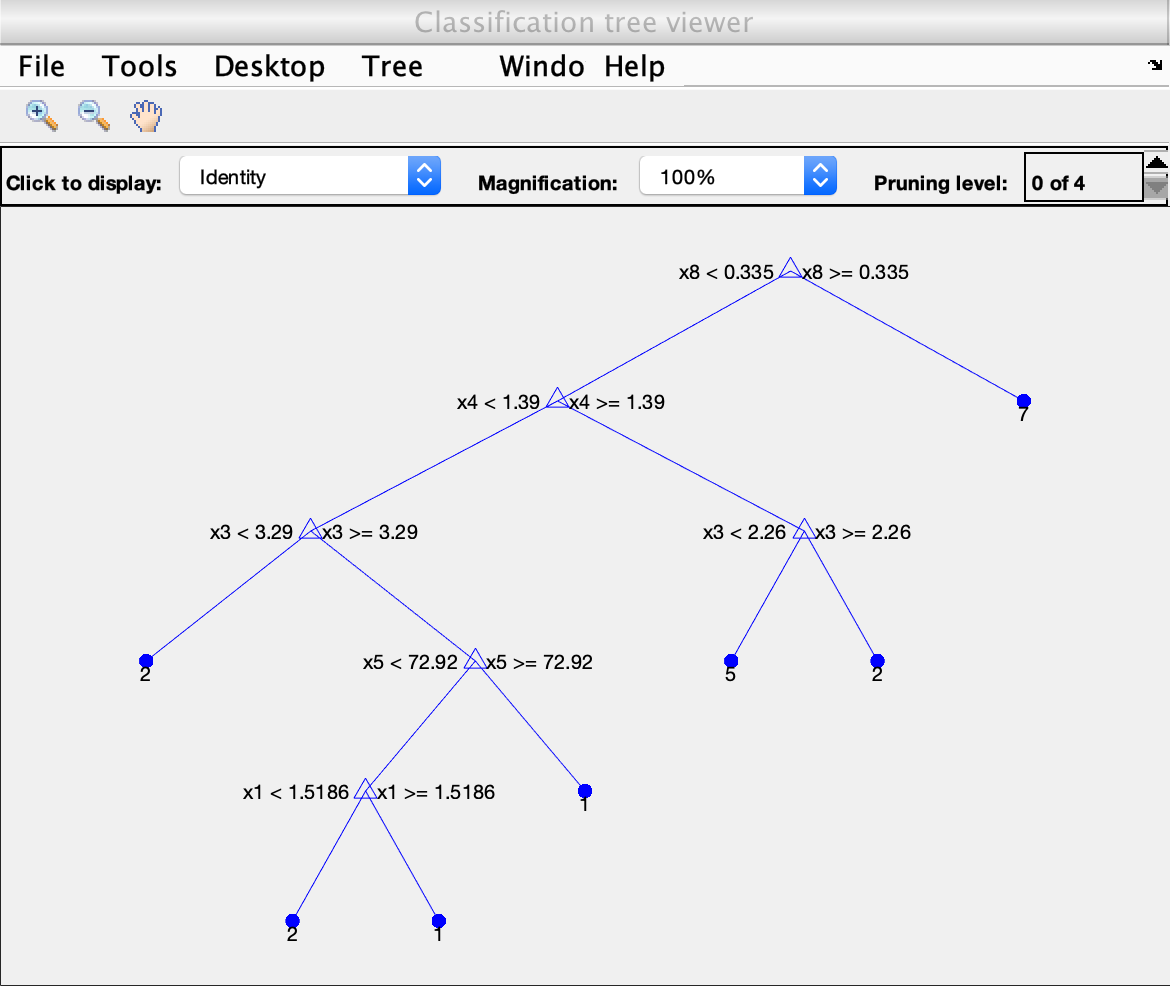


% loss
dt_loss = loss(dt_final, test_X, test_Y)

elapsed time for creating the model is 0.039626

**Add pruning:**

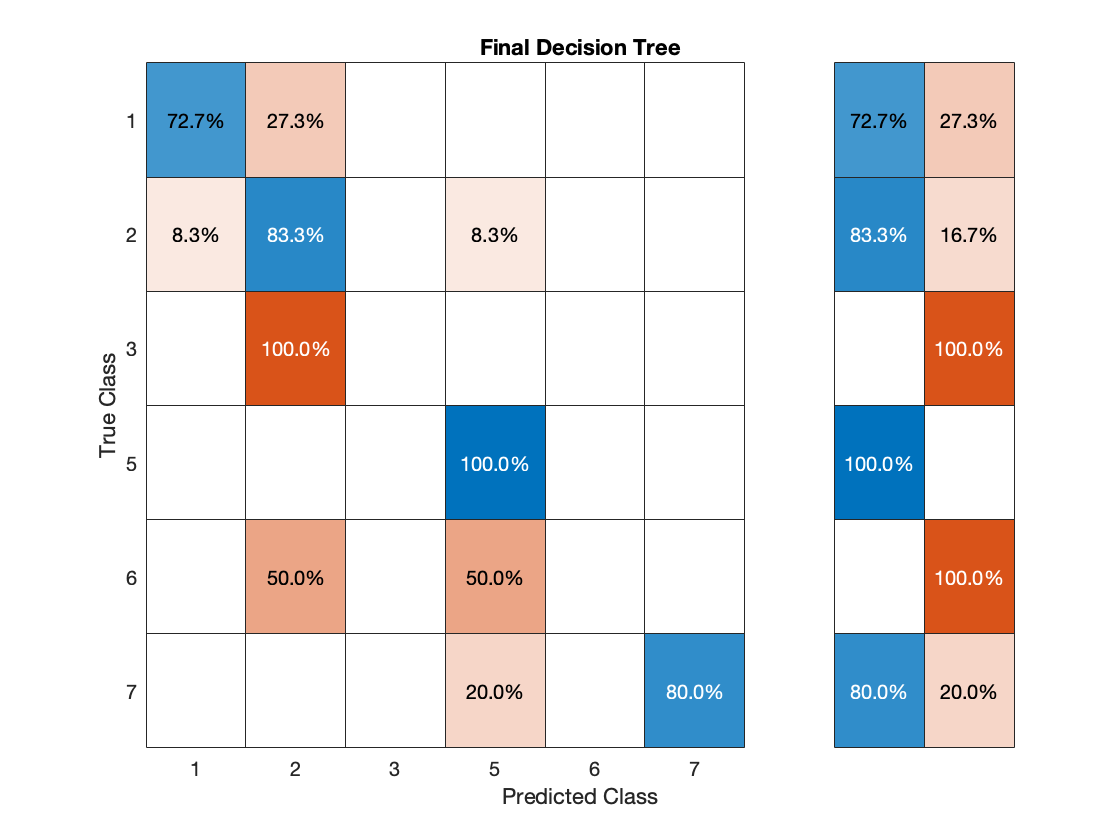

% Prune the model to level 1
dt_finalpruned = prune(dt_final,'Level',1); % FINAL DT MODEL

% make predicitions on validation set
dt_FinalPrunedPred_val = predict(dt_finalpruned, val_X);


confusionchart(val_Y,dt_FinalPrunedPred_val,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','Final Decision Tree Pruned Validation Set')


resuberror = 0.2600

dt_finalprunedloss_val = loss(dt_finalpruned, val_X, val_Y)



dt_loss = 0.3032

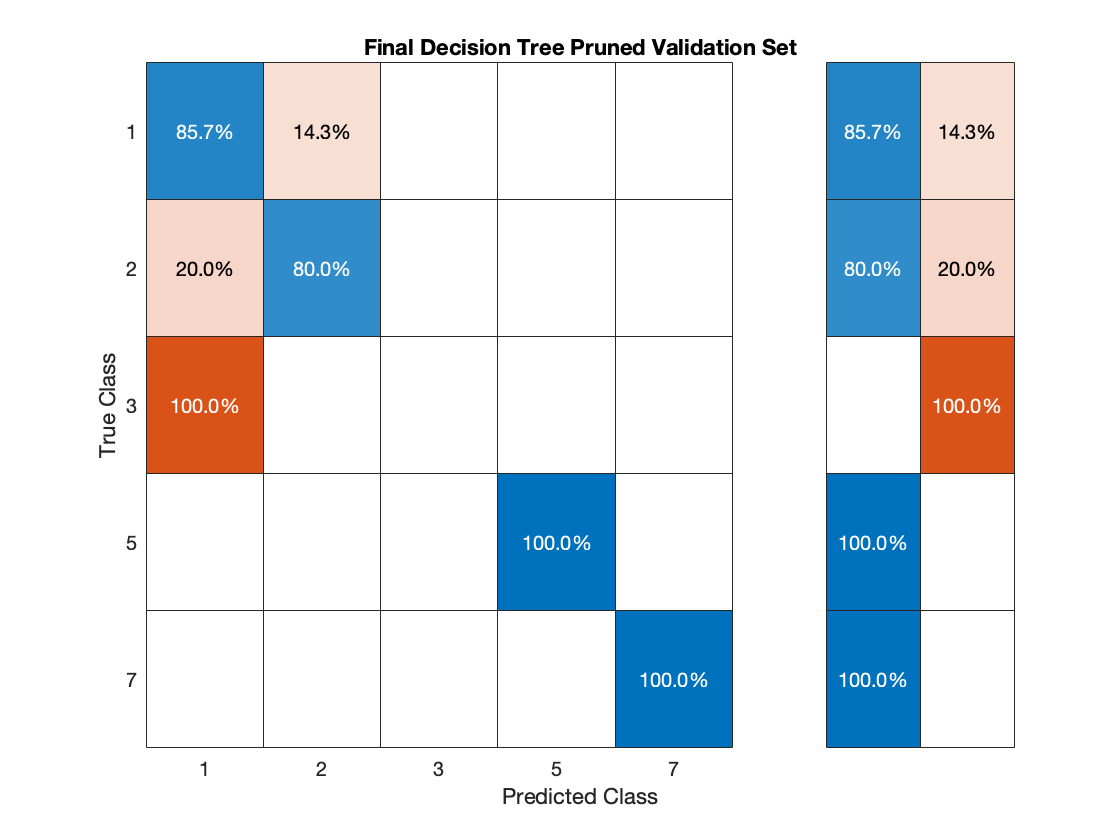

% make predicitions on test set
dt_FinalPrunedPred = predict(dt_finalpruned, test_X);

% confusion matrix test set
confusionchart(test_Y,dt_FinalPrunedPred,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','Final Decision Tree Pruned Test Set')

dt_finalprunedloss_test = loss(dt_finalpruned, test_X, test_Y)

% calculate resubstitution/In-sample classification error
resuberror_pruned = resubLoss(dt_finalpruned)


% loss

dt_finalprunedloss_val = 0.2114

dt_loss = loss(dt_finalpruned, test_X, test_Y)

**Cross validation:**

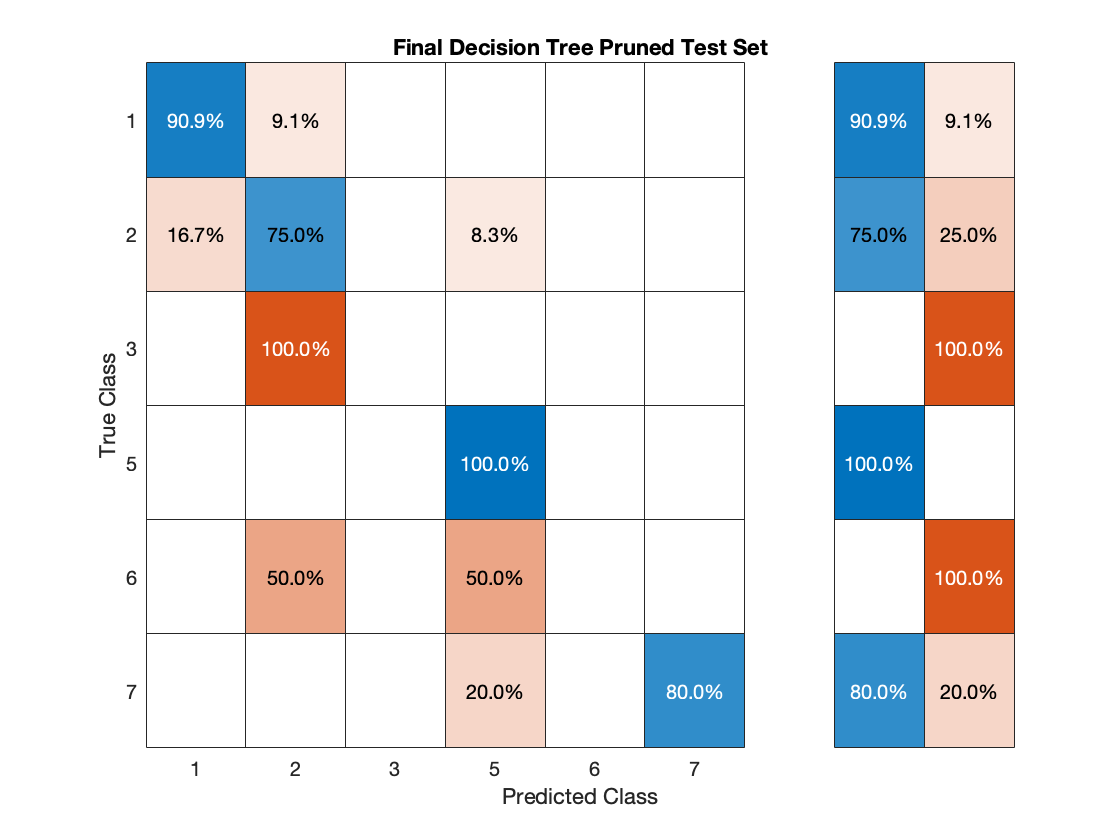

% Perform cross-validation
dt_cvfinal = crossval(dt_finalpruned, 'KFold', 5);
dt_cvlossfinal = kfoldLoss(dt_cvfinal)

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(dt_cvfinal, 'LossFun', 'ClassifError')

## **4. Comparison of Methods & Summary**

**Random Forests:**

disp('###################  COMPARISON OF METHODS  #####################')

dt_finalprunedloss_test = 0.2786

disp ('RANDOM FORESTS:')
% confusion matrix
confusionchart(test_Y,rf_finalfit,'Normalization','row-normalized','RowSummary','row-normalized', ...

resuberror_pruned = 0.3267

    'Title','Final Random Forest Model')

% loss of inital model and final model

dt_loss = 0.2786

rf_loss
rf_loss_final

% optimal number of trees
fprintf('\nMinimum cross validated classification error = %0.5f',rf_minErr)

dt_cvlossfinal = 0.3933

fprintf('\nOptimal Num. Trees = %d',rf_minErridx);

**Decision Tree:**

disp('DECISION TREE:')

validationAccuracy = 0.6067

%confusion matrix
confusionchart(test_Y,dt_FinalPrunedPred,'Normalization','row-normalized','RowSummary','row-normalized', ...
    'Title','Final Decision Tree')
% loss

###################  COMPARISON OF METHODS  #####################


dt_loss = loss(dt_finalpruned, test_X, test_Y)

RANDOM FORESTS:



% optimal number of leaves
fprintf('\nMinimum classification error = %0.5f',dt_minErr)

fprintf('\nOptimal Num. Leaves = %d',dt_minErridx);

% accuracy of Random forest
rf_matches = 0;

rf_loss_final = 0.1359

rf_loss = 0.2592

for i = 1:size(rf_finalfit,1)
    if rf_finalfit(i)==test_Y(i)
        rf_matches = rf_matches + 1;


Minimum cross validated classification error = 0.21333

    end


Optimal Num. Trees = 49

end
rf_accuracy = rf_matches/size(rf_finalfit,1)


DECISION TREE:


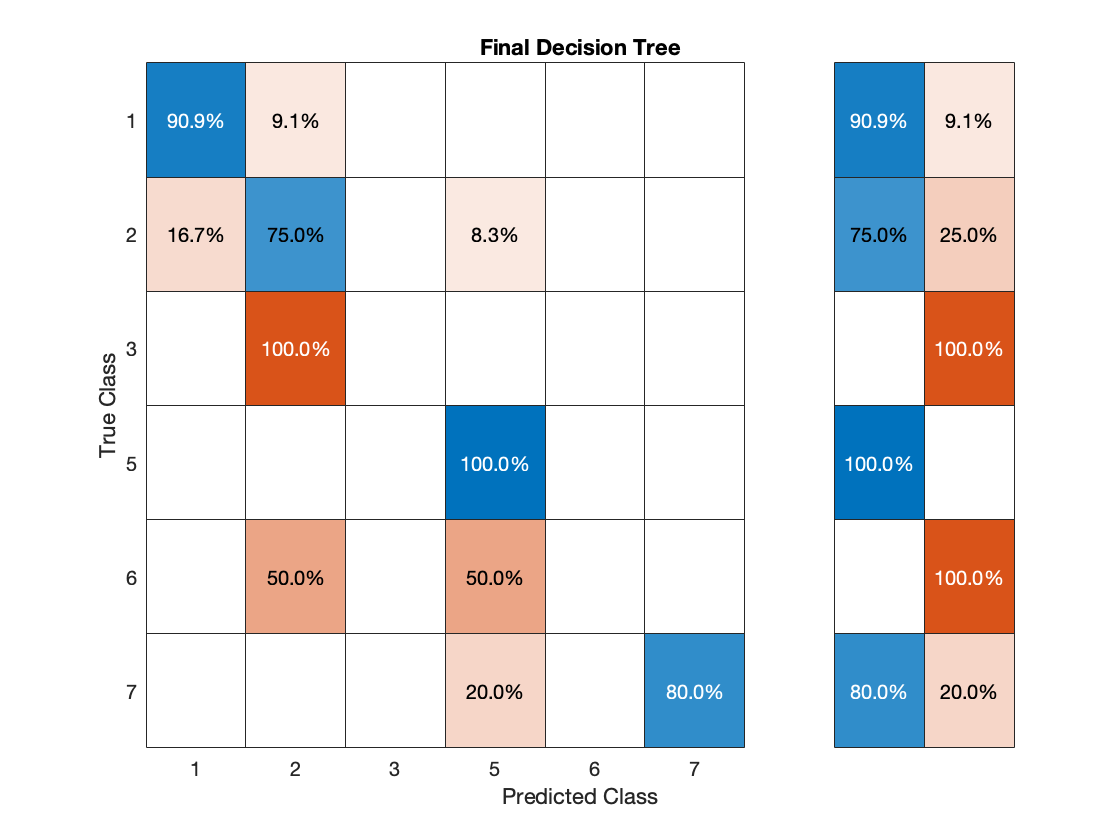


% accuracy of Decision Tree
dt_matches = 0;

for i = 1:size(dt_FinalPrunedPred,1)
    if dt_FinalPrunedPred(i)==test_Y(i)

dt_loss = 0.2786

        dt_matches = dt_matches + 1;
    end
end


Minimum classification error = 0.30667

dt_accuracy = dt_matches/size(dt_FinalPrunedPred,1)


Optimal Num. Leaves = 15



% % compare accuracies of the two models
[h,p,dt_classloss,rf_classloss] = testcholdout(dt_FinalPrunedPred, rf_finalfit,test_Y)
% dt_accuracy = 1 - dt_classloss
% rf_accuracy = 1 - rf_classloss

rf_accuracy = 0.8438

dt_accuracy = 0.7500

h = logical
   0

p = 0.2187

dt_classloss = 0.2500

rf_classloss = 0.1563

Comparing the two models, one can see that there is significantly less missclassification from the Random Forest model.

`h = 0` indicates to not reject the null hypothesis that the two models have equal predictive accuracies.

`h = 1` indicates to reject the null hypothesis that the two models have differing predictive accuracies.